# Laboratorio - Analisis y simulacion de robot industrial 

## 1.Localizacion de ruta 

De acuerdo al grafico de la siguiente figura se crea la trayectoria a trozos en un plano XY que posteriormente sera rotado y transladado al espacio de trabajo del robot.

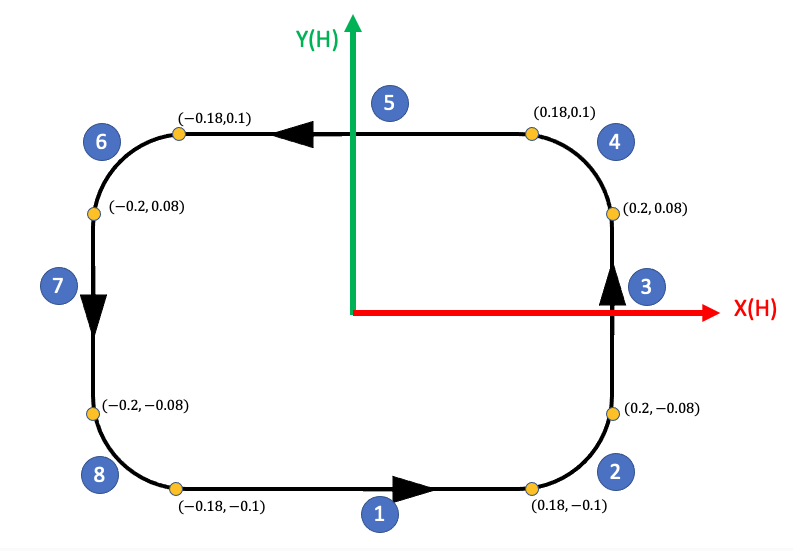

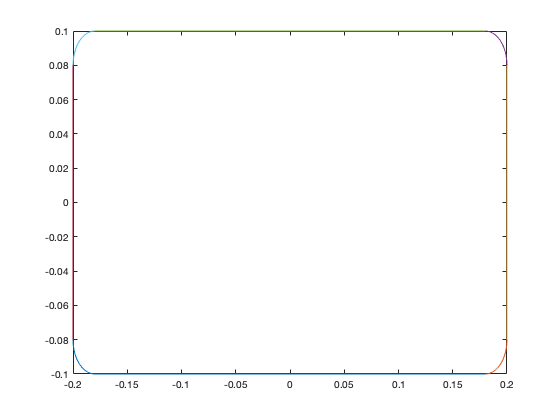

clc
clear
close all

a = 0.18; %distancia en x
b = 0.1;  %distancia en y
c = 0.08; %centro en y de los semicirculos
r = 0.02; %radio 

%%Ruta 1
x = -a:0.01:a;
len = size(x);
y = -b*ones(1,len(2));
z = zeros(1,len(2));
R1 = [x;y;z];
traye = R1;

figure()
plot(x,y);
hold on

%%Ruta 2
t = 3*pi/2:pi/20:2*pi;
x = 0.02*cos(t)+a;
y = 0.02*sin(t)-c;
len = size(x);
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);
%%Ruta 3
y = -c:0.01:c;
len = size(y);
x = (a+r)*ones(1,len(2));
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 4
t = 0:pi/20:pi/2;
x = 0.02*cos(t)+a;
y = 0.02*sin(t)+c;
len = size(x);
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 5
x = -a:0.01:a;
len = size(x);
y = b*ones(1,len(2));
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 6
t = pi/2:pi/20:pi;
x = 0.02*cos(t)-a;
y = 0.02*sin(t)+c;
len = size(x);
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 7
y = -c:0.01:c;
len = size(y);
x = -(a+r)*ones(1,len(2));
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 8
t = pi:pi/20:3*pi/2;
x = 0.02*cos(t)-a;
y = 0.02*sin(t)-c;
len = size(x);
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

hold off

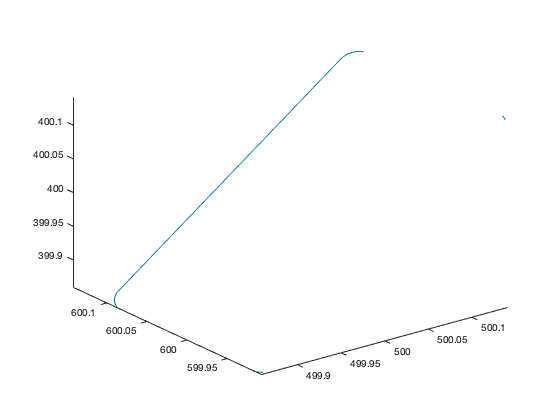


%Matriz de Rotacion
R = [1/sqrt(2),0,-1/sqrt(2);
     0        ,1,0         ;
     1/sqrt(2),0, 1/sqrt(2)];


% Desplazamiento
x = 500;
y = 600;
z = 400;

%% Rotacion y dezplazamiento de la trayectoria

len = size(traye);
for i = 1:len(2)
    traye(1:3,i) = R*traye(1:3,i);
end

traye(1,:) = x + traye(1,:);
traye(2,:) = y + traye(2,:);
traye(3,:) = z + traye(3,:);

figure
plot3(traye(1,:),traye(2,:),traye(3,:))

## 2.Caracteristicas y modelo del robot

- Imagen del robot. https://www.robots.com/robots/fanuc-lr-mate-200ib

http://geek.nmt.edu/~bruder/final_project_files/Fanuc%20LR%20Mate_200ib_200ib_3l.pdf

			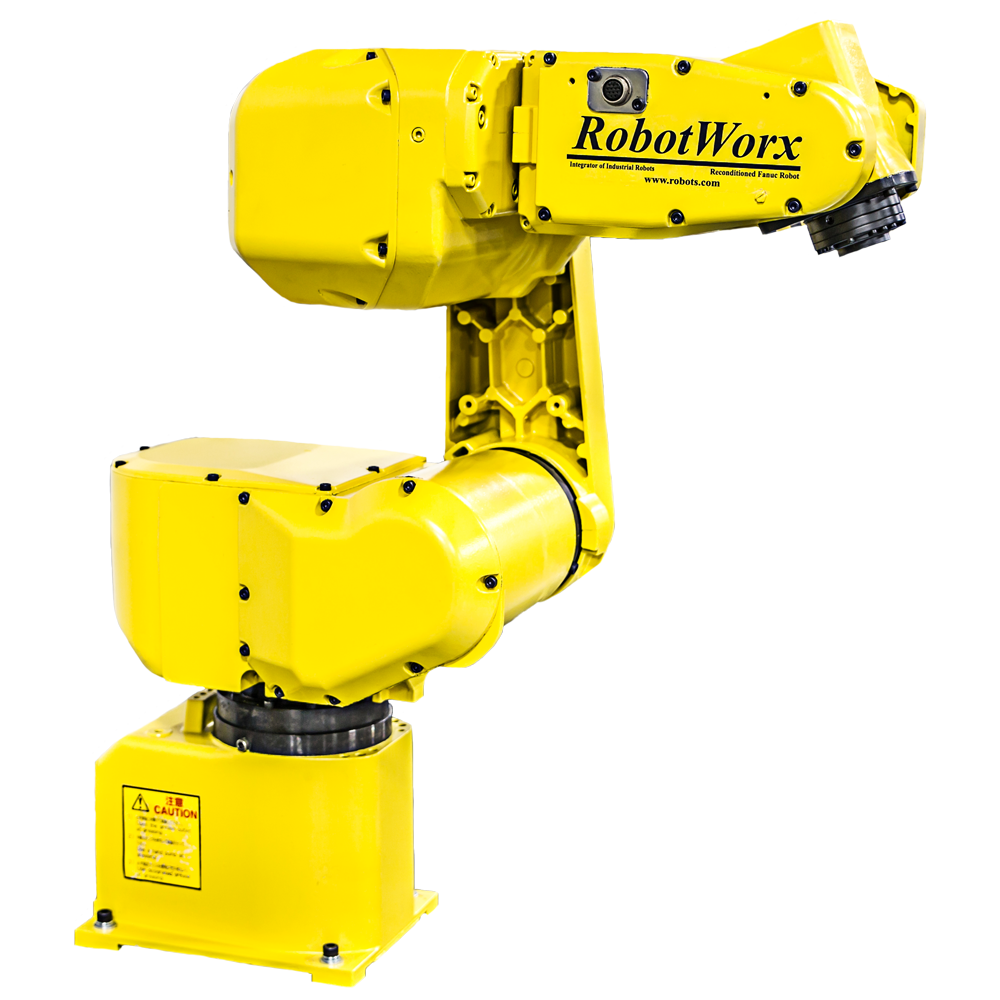		

2. Capacidad de carga = 5 kg.

3. Alcance vertical y horizontal. 

H-Reach: 7000 mm			

4. Repetibilidad. = **± 0.04mm**

5. Grafica(s) de espacio alcanzable.

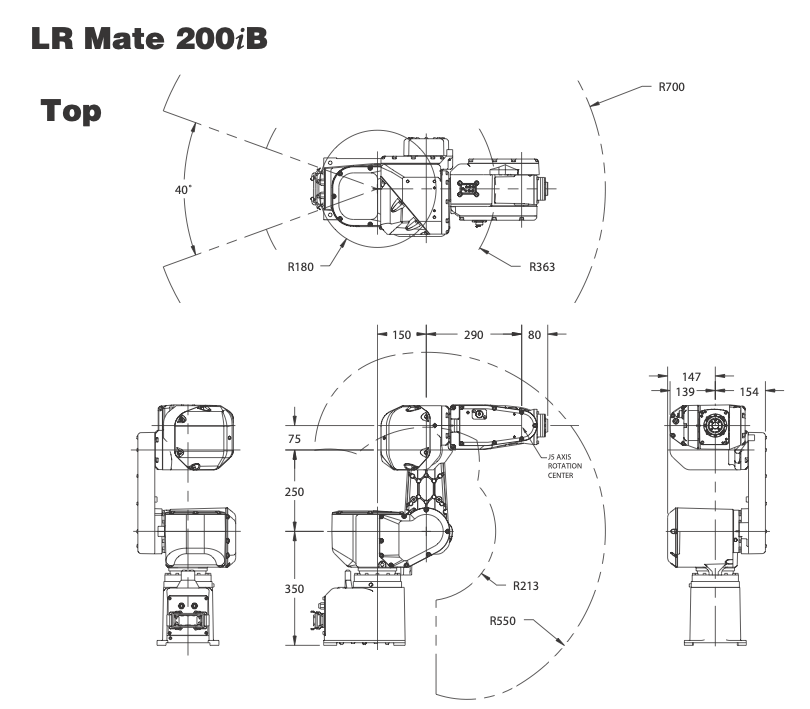

6. Tabla de parametros DH.

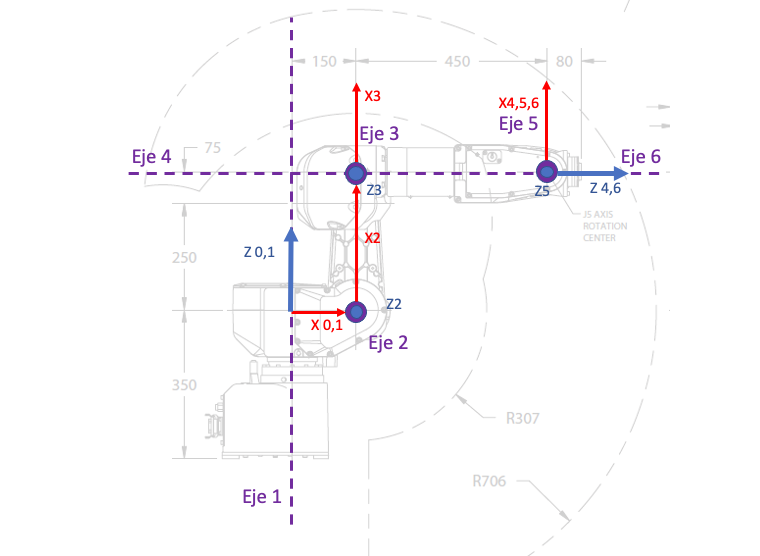

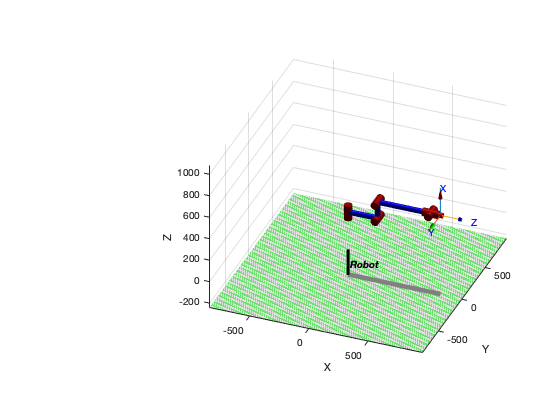

clc;clear;close all
l0 = 350; l1 = 250; l2 = 150; l3 = 450;l4 = 80;
ws= [-70 80 -70 80 -20 90]*12;
plot_options = {'workspace',ws,'scale',0.5,'view',[-100 30], 'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
L(1) = Link('revolute'  ,'alpha', 0,    'a',   0, 'd',  l0,'offset',0,'qlim', [-8*pi/9 8*pi/9],   'modified');
L(2) = Link('revolute'  ,'alpha', pi/2, 'a',  l1, 'd',   0,'offset',pi/2, 'qlim',  [-7*pi/36 5*pi/6],   'modified');
L(3) = Link('revolute'  ,'alpha', 0,    'a',  l2, 'd',   0,'offset',0, 'qlim',  [-11*pi/18 103*pi/90],   'modified');
L(4) = Link('revolute'  ,'alpha',  pi/2,'a',   0, 'd',  l3,'offset',  0, 'qlim',    [-19*pi/18 19*pi/18],   'modified');
L(5) = Link('revolute'  ,'alpha', -pi/2,'a',   0, 'd',   0,'offset',  0, 'qlim',    [-2*pi/3 2*pi/3],   'modified');
L(6) = Link('revolute'  ,'alpha', pi/2, 'a',   0, 'd',   0,'offset',  0, 'qlim',    [-2*pi 2*pi],   'modified');

Robot = SerialLink(L,'name','Robot','plotopt',plot_options);
Robot.tool = [1,0,0,0;
              0,1,0,0;
              0,0,1,l4;
              0,0,0,1];
Robot.teach()

7. Que software utiliza el fabricante para diseño de celdas o programacion. 

FANUC ROBOGUIDE SIMULATION SOFTWARE

## PARTE 2	

### 6. Iniciando

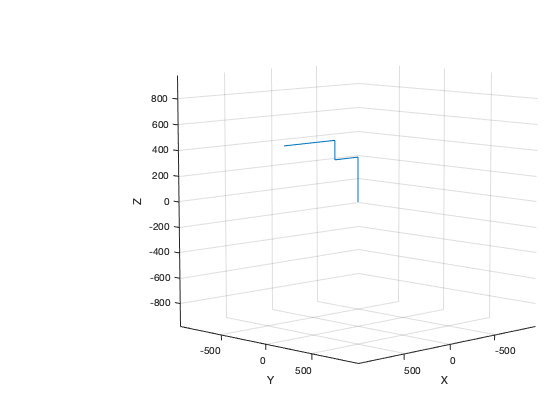

ans =   Axes (Primary) with properties:

             XLim: [-978 978]
             YLim: [-978 978]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [205.7548 56.6871 306.1935 324.6626]
            Units: 'pixels'

  Show all properties


MTH01 = double(L(1).A(0));
MTH02 = double(L(2).A(0));
MTH03 = double(L(3).A(0));
MTH04 = double(L(4).A(0));
MTH05 = double(L(5).A(0));
MTH06 = double(L(6).A(0));
Efec = double(Robot.tool);

robot = rigidBodyTree;

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
jnt1.HomePosition = 0;
setFixedTransform(jnt1,MTH01);
body1.Joint = jnt1;

addBody(robot,body1,'base')

body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt2.HomePosition = 0;
setFixedTransform(jnt2,MTH02);
body2.Joint = jnt2;

addBody(robot,body2,'body1')

body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
jnt3.HomePosition = 0;
setFixedTransform(jnt3,MTH03);
body3.Joint = jnt3;

addBody(robot,body3,'body2')

body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt4.HomePosition = 0;
setFixedTransform(jnt4,MTH04);
body4.Joint = jnt4;

addBody(robot,body4,'body3')

body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');
jnt5.HomePosition = 0;
setFixedTransform(jnt5,MTH05);
body5.Joint = jnt5;

addBody(robot,body5,'body4')

body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','revolute');
jnt6.HomePosition = 0;
setFixedTransform(jnt6,MTH06);
body6.Joint = jnt6;

addBody(robot,body6,'body5')

bodyEndEffector = rigidBody('endeffector');
setFixedTransform(bodyEndEffector.Joint,Efec);
addBody(robot,bodyEndEffector,'body6');

%%addVisual(body,"Mesh",filename)
% Robot2 = loadrobot("fanucLRMate200ib")
% showdetails(Robot2)

show(robot)

### 7. Modelo geometrico directo			

Halle el modelo geometrico directo de su robot asignado usando MTH.

syms theta1 theta2 theta3 theta4 theta5 theta6
MTH01 = (L(1).A(theta1));
MTH12 = (L(2).A(theta2));
MTH23 = (L(3).A(theta3));
MTH34 = (L(4).A(theta4));
MTH45 = (L(5).A(theta5));
MTH56 = (L(6).A(theta3));
Efec = Robot.tool;

threshold = 1e-7;
MTHef = simplify( MTH01*MTH12*MTH23*MTH34*MTH45*MTH56);
MTHef = MTHef*Efec;
% MTHef = mapSymType(MTHef,'rational', @(x) piecewise(abs(x)<=threshold, 0, x))
q1 = [0.5,0.2,0.4,0.5,0,1.5];
q2 = [-pi/2,0.3,0,pi/2,0.4,1.2];
q3 = [0,1,-0.5,2,1,0.5];
q4 = [-1,-0.3,-pi/5,0.4,0.2,1];

x1 = subs(MTHef,[theta1 theta2 theta3 theta4 theta5 theta6],q1);
x2 = subs(MTHef,[theta1 theta2 theta3 theta4 theta5 theta6],q2);
x3 = subs(MTHef,[theta1 theta2 theta3 theta4 theta5 theta6],q3);
x4 = subs(MTHef,[theta1 theta2 theta3 theta4 theta5 theta6],q4);